### sonar

clc;clear

##   1. base de datos

-     en la clase 1 van los 1

-     en la clase 0 van los 0

### sonar

% load('sonar.mat');
% variables=1:60;
% target=61;
% clase1=sonarOrdenada(1:111,[variables target]);
% clase0=sonarOrdenada(111:end,[variables target]);

### cancerMama

% load('cancerMama.mat')
% variables=1:30;
% target=31;
% clase0=Datos(1:354,[variables target]);%esta es en donde van los 0
% clase1=Datos(354:end,[variables target]);%esta es en donde van los 1


### ovarian cancer


load('C:\Program Files\MATLAB\R2020a\toolbox\stats\statsdemos\ovariancancer.mat')
obs(1:121,4001)=ones();
obs(122:end,4001)=zeros();
obs=double(obs);

variables=1:4000;
target=4001;

clase1=obs(1:121,[variables target]);%esta es en donde van los 1
clase0=obs(122:end,[variables target]);%esta es en donde van los 0

Fit the neighborhood component analysis model for classification.

dejar los nombres de clase0 y clase1

X=[clase1(:,1:end-1);clase0(:,1:end-1)];
y=[clase1(:,end);clase0(:,end)];
mdl = fscnca(X,y,'Solver','sgd','Verbose',1);


 o Tuning initial learning rate: NumTuningIterations = 20, TuningSubsetSize = 100

|===============================================|
|    TUNING    | TUNING SUBSET |    LEARNING    |
|     ITER     |   FUN VALUE   |      RATE      |
|===============================================|
|            1 |  1.690353e+01 |   2.000000e-01 |
|            2 |  1.625301e+01 |   4.000000e-01 |
|            3 |  1.501893e+01 |   8.000000e-01 |
|            4 |  1.280128e+01 |   1.600000e+00 |
|            5 |  9.208986e+00 |   3.200000e+00 |
|            6 |  4.525878e+00 |   6.400000e+00 |
|            7 |  6.206117e-01 |   1.280000e+01 |
|            8 | -7.078296e-01 |   2.560000e+01 |
|            9 | -7.078296e-01 |   2.560000e+01 |
|           10 | -7.078296e-01 |   2.560000e+01 |
|           11 | -7.078296e-01 |   2.560000e+01 |
|           12 | -7.078296e-01 |   2.560000e+01 |
|           13 | -7.752480e-01 |   5.120000e+01 |
|           14 | -7.752480e-01 |   5.120000e+01 |
|           15 |

mirar la grafica y poner un limite segun la tolerancia

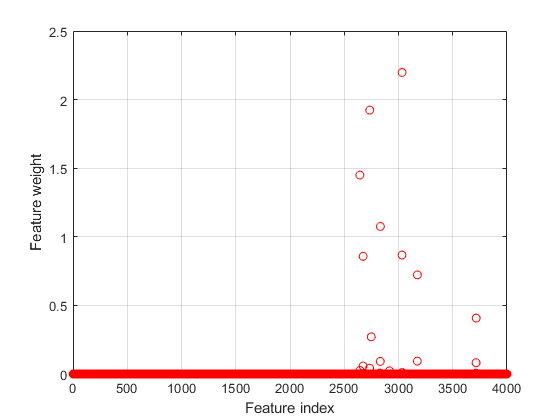

figure()
plot(mdl.FeatureWeights,'ro')
grid on
xlabel('Feature index')
ylabel('Feature weight')

tol    = 0.3;
variables = find(mdl.FeatureWeights > tol*max(1,max(mdl.FeatureWeights)))'

variables =         2644        2674        2735        2833        3032        3033        3174
